# 시스템 모델링 입문 (한글판)

원문 : Control Tutorials for MATLAB and Simulink — Introduction: System Modeling 한글 정리 : 제어시스템설계 · 충남대학교 자율운항시스템공학과

제어 설계의 첫걸음은 **제어할 대상의 수학 모델을 세우는 것**입니다. 모델은 물리 법칙에서 유도하거나 실험 데이터에서 얻습니다.

이 문서에서 다루는 것

- 고전적인 두 시스템의 모델 — **질량-스프링-댐퍼**와 **RLC 회로**

- 두 시스템의 자유응답을 파라미터를 바꿔 가며 살펴보기

- 미분방정식 · 상태공간 · 전달함수 **세 표현 사이를 오가는 법**

오늘 쓰는 MATLAB 명령

- `tf` — 전달함수 만들기

- `ss` — 상태공간 만들기

- `pole`, `damp` — 극점과 감쇠비 읽기

- `initial`, `step` — 자유응답과 계단응답

clc; close all;
s = tf('s');

## 1. 예제 하나 — 질량-스프링-댐퍼

벽에 스프링 $k$ 와 댐퍼 $b$ 로 매달린 질량 $m$ 을 힘 $F(t)$ 로 미는 문제입니다. 변위 $x$ 는 **오른쪽을 **$+$ 로 잡습니다.

$x = 0$ 은 스프링이 늘어나지도 줄어들지도 않은 자리입니다.

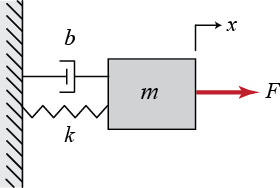

질량-스프링-댐퍼 장치 그림

## 1-1. 자유물체도

물체 하나만 떼어 내서 걸리는 힘을 전부 그립니다.

- 스프링 힘은 **변위**에 비례한다 — $k\,x$

- 댐퍼 힘은 **속도**에 비례한다 — $b\,\dot{x}$

- 두 힘 모두 **운동을 방해하는 쪽**이므로 $x$ 의 음의 방향으로 그린다

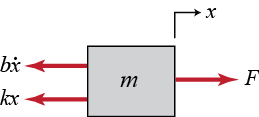

자유물체도 : 두 힘 모두 운동을 방해한다

## 1-2. 뉴턴의 제2법칙으로 지배방정식 세우기

$y$ 방향으로는 힘이 없고, $x$ 방향만 보면 됩니다.


$$\sum F_x = F(t) - b\,\dot{x} - k\,x = m\,\ddot{x}$$


이 식을 **지배방정식**이라고 합니다. 시스템의 동적 상태를 완전히 규정하는 식이며, 나중에 이 식으로 어떤 입력 $F(t)$ 에 대한 응답이든 계산할 수 있습니다.

항을 옮겨 보기 좋게 정리하면 이렇습니다.


$$m\,\ddot{x} + b\,\dot{x} + k\,x = F(t)$$


왼쪽이 **시스템이 스스로 갖는 성질**, 오른쪽이 **밖에서 넣는 힘**입니다.

## 1-3. 상태공간 표현

2계 미분방정식 하나를 **1계 미분방정식 두 개**로 바꾸는 일입니다. 상태로는 위치와 속도를 고릅니다.


$$\mathbf{x} = \left[\begin{array}{c} x \\ \dot{x} \end{array}\right]$$


**왜 이 둘인가 — 에너지로 생각하면 명확합니다**

- 위치 $x$ 는 스프링에 저장된 **위치에너지**를 결정한다

- 속도 $\dot{x}$ 는 질량이 갖는 **운동에너지**를 결정한다

- 댐퍼는 에너지를 **버리기만** 하고 저장하지 않는다. 그래서 상태가 아니다

상태를 고를 때는 **에너지를 저장하는 곳이 어디인가**를 물어보면 됩니다.

상태방정식은 이렇게 됩니다.


$$\left[\begin{array}{c}\dot{x}\\ \ddot{x}\end{array}\right] = \left[\begin{array}{cc} 0 & 1 \\ -\frac{k}{m} & -\frac{b}{m}\end{array}\right] \left[\begin{array}{c}x\\ \dot{x}\end{array}\right] + \left[\begin{array}{c}0\\ \frac{1}{m}\end{array}\right] F(t)$$


위치를 제어하고 싶다면 출력방정식은 이렇습니다.


$$y = \left[\begin{array}{cc}1 & 0\end{array}\right] \left[\begin{array}{c}x\\ \dot{x}\end{array}\right]$$


m = 1;  b = 0.2;  k = 1;
A = [0 1; -k/m -b/m];
B = [0; 1/m];
C = [1 0];
D = 0;
sys_ss = ss(A, B, C, D);

fprintf('=== 상태공간 (m=%.1f, b=%.1f, k=%.1f) ===\n', m, b, k);
disp('A ='); disp(A);
disp('B ='); disp(B);
fprintf('C = %s ,  D = %g\n\n', mat2str(C), D);

## 1-4. 전달함수 표현

라플라스 영역으로 옮긴 뒤 **출력 나누기 입력**으로 정리한 것입니다. 초기조건을 전부 $0$ 으로 두고 변환하면


$$m\,s^2 X(s) + b\,s\,X(s) + k\,X(s) = F(s)$$


이므로


$$\frac{X(s)}{F(s)} = \frac{1}{m s^2 + b s + k}$$


G_msd = tf(1, [m b k]);
fprintf('=== 전달함수 ===\n');
G_msd
fprintf('  극점 : %s\n', mat2str(round(pole(G_msd).', 4)));
fprintf('  상태공간에서 얻은 것과 차이 : %.2e\n\n', ...
        max(abs(sort(pole(tf(sys_ss))) - sort(pole(G_msd)))));

## 2. 자유응답 — 파라미터가 응답을 어떻게 바꾸는가

전달함수 분모의 근(**극점**)이 시스템의 자연스러운 과도 거동을 정합니다. 근의 공식을 쓰면


$$\text{극점} = \frac{-b \pm \sqrt{b^2 - 4mk}}{2m}$$


판별식의 부호로 성격이 갈립니다.

- **과감쇠** — 감쇠가 충분히 크면 극점이 서로 다른 실수. 진동 없이 지수적으로 감쇠

- **임계감쇠** — 판별식이 $0$. 진동 없이 가장 빠르게 감쇠

- **부족감쇠** — 감쇠가 작으면 극점이 복소수. 진폭이 줄면서 **진동**

원문의 라이브 스크립트에는 $m$, $b$, $k$ 를 슬라이더로 바꾸는 기능이 있습니다. 여기서는 대표적인 값 네 개를 한 번에 비교합니다.

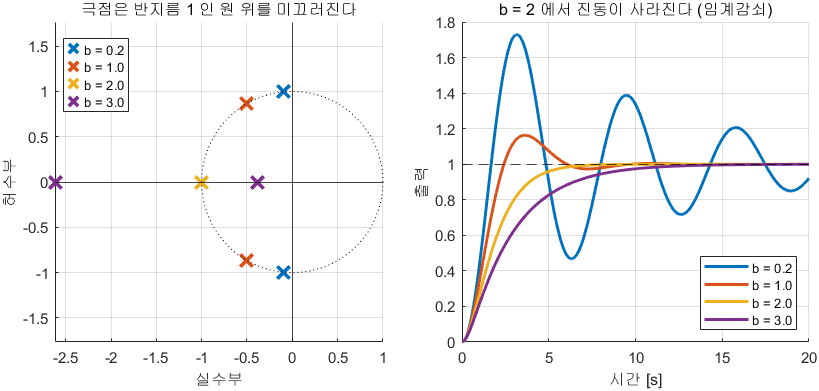

댐퍼를 키우면 극점이 실축으로 모인다

fprintf('=== 댐퍼에 따른 성격 변화 (m = 1, k = 1) ===\n');
fprintf('    b     판별식      극점                        성격\n');
fprintf('  -----  --------  --------------------------  ----------\n');
for bb = [0.2 1.0 2.0 3.0]
    disc = bb^2 - 4*m*k;
    rr = roots([m bb k]);
    if     disc < -1e-9,      st = '부족감쇠 (진동)';
    elseif abs(disc) < 1e-9,  st = '임계감쇠';
    else,                     st = '과감쇠';
    end
    fprintf('  %5.1f  %8.2f  %-26s  %s\n', bb, disc, mat2str(round(rr.',3)), st);
end
fprintf('\n');

## 2-1. 초기조건만 주고 놓아 보기

힘을 전혀 주지 않고 물체를 $0.5\,\mathrm{m}$ 당겨 놓았다가 놓습니다. 이것이 **자유응답**입니다. 전달함수로는 표현할 수 없고 상태공간이라야 됩니다.

t = (0:0.02:40)';
sys_full = ss(A, B, eye(2), [0;0]);       % 위치와 속도를 모두 출력
y_free = initial(sys_full, [0.5; 0], t);

tiledlayout(2,1,'TileSpacing','compact');
nexttile
plot(t, y_free(:,1), 'LineWidth', 2); grid on;
ylabel('위치 [m]'); title('자유응답 : 힘 없이 놓았을 때');
nexttile
plot(t, y_free(:,2), 'LineWidth', 2, 'Color', [0.85 0.33 0.10]); grid on;
xlabel('시간 [s]'); ylabel('속도 [m s^{-1}]');

위치가 최대일 때 속도가 $0$ 이고, 위치가 $0$ 을 지날 때 속도가 최대입니다. 그네를 떠올리면 자연스러운 결과입니다. 위치에너지와 운동에너지가 서로 주고받고 있는 것입니다.

## 3. 예제 둘 — RLC 회로

기계 시스템에 뉴턴 법칙이 있듯, 전기 회로에는 **키르히호프 법칙**이 있습니다.

- **전류 법칙 (KCL)** — 한 마디로 들어오는 전류의 합은 나가는 전류의 합과 같다

- **전압 법칙 (KVL)** — 닫힌 고리를 한 바퀴 돌면 전압 차의 합이 $0$ 이다

저항 · 인덕터 · 커패시터를 직렬로 이은 것을 **RLC 회로**라고 합니다. 고리가 하나뿐이므로 전류는 어디서나 같습니다.

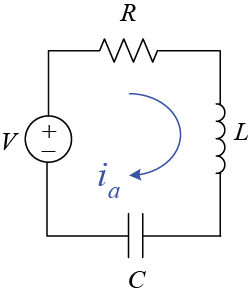

RLC 회로

## 3-1. 지배방정식

고리를 한 바퀴 돌며 KVL 을 쓰면


$$V(t) - R\,i - L\,\frac{di}{dt} - \frac{1}{C}\int i\,dt = 0$$


여기서 **아주 중요한 사실**이 하나 보입니다. 이 식이 질량-스프링-댐퍼의 식과 **완전히 같은 꼴**입니다.

전하 $q = \int i\,dt$ 로 쓰면


$$L\,\ddot{q} + R\,\dot{q} + \frac{1}{C}\,q = V(t)$$


한 칸씩 대응시키면 이렇습니다.

| 기계 | 전기 | 하는 일 | |---|---|---| | 변위 $x$ | 전하 $q$ | 쌓이는 양 | | 속도 $\dot{x}$ | 전류 $i$ | 흐르는 양 | | 질량 $m$ | 인덕턴스 $L$ | 변화를 싫어한다 | | 댐퍼 $b$ | 저항 $R$ | 에너지를 버린다 | | 스프링 $k$ | $1/C$ | 되돌리려 한다 | | 힘 $F$ | 전압 $V$ | 밖에서 넣는 것 |

이런 대응을 **상사(analogy)** 라고 합니다. 하나를 이해하면 다른 것은 공짜로 이해됩니다.

## 3-2. 상태공간과 전달함수

상태로는 커패시터의 전하와 회로의 전류를 고릅니다. (앞에서와 같은 기준입니다 — 에너지를 저장하는 곳)


$$\mathbf{x} = \left[\begin{array}{c} q \\ i \end{array}\right], \qquad q = \int i\,dt$$



$$\left[\begin{array}{c}\dot{q}\\ \dot{i}\end{array}\right] = \left[\begin{array}{cc} 0 & 1 \\ -\frac{1}{LC} & -\frac{R}{L}\end{array}\right] \left[\begin{array}{c}q\\ i\end{array}\right] + \left[\begin{array}{c}0\\ \frac{1}{L}\end{array}\right] V(t)$$


커패시터 전압을 출력으로 보면 $y = q/C$ 이므로


$$\frac{V_C(s)}{V(s)} = \frac{1/(LC)}{s^2 + \frac{R}{L}s + \frac{1}{LC}}$$


L_ = 1;  R_ = 0.4;  C_ = 1;
A_rlc = [0 1; -1/(L_*C_) -R_/L_];
B_rlc = [0; 1/L_];
C_rlc = [1/C_ 0];
sys_rlc = ss(A_rlc, B_rlc, C_rlc, 0);
G_rlc   = tf(sys_rlc);

fprintf('=== RLC 회로 (L=%.1f, R=%.1f, C=%.1f) ===\n', L_, R_, C_);
G_rlc
fprintf('  극점 : %s   <- 복소수, 즉 진동합니다\n\n', mat2str(round(pole(G_rlc).',3)));

t2 = (0:0.02:30)';
plot(t2, step(G_rlc, t2), 'LineWidth', 2); hold on;
plot(t2, step(tf(1,[1 1]), t2), '--', 'LineWidth', 2);
yline(1, 'k:'); grid on;
xlabel('시간 [s]'); ylabel('출력 (크기를 맞춘 값)');
legend('RLC (2차) — 흔들린다', 'RC (1차) — 안 흔들린다', '최종값', 'Location','southeast');
title('에너지를 저장하는 곳이 둘이면 진동한다');

## 4. 표현 사이를 오가기

MATLAB 에서는 세 표현을 자유롭게 바꿀 수 있습니다.

| 하고 싶은 것 | 명령 | |---|---| | 상태공간 $\rightarrow$ 전달함수 | `tf(sys_ss)` | | 전달함수 $\rightarrow$ 상태공간 | `ss(sys_tf)` | | 영점-극점 형태로 | `zpk(sys)` | | 극점만 보기 | `pole(sys)` 또는 `eig(A)` |

수식으로는 이렇습니다.


$$G(s) = C\,(sI - A)^{-1} B + D$$


유도는 두 줄이면 됩니다. $\dot{x} = Ax + Bu$ 를 라플라스 변환하면


$$(sI - A)X(s) = B\,U(s) \quad \Rightarrow \quad X(s) = (sI-A)^{-1}B\,U(s)$$


이것을 $Y = CX + DU$ 에 넣으면 위 식이 나옵니다.

fprintf('=== 표현 바꾸기 확인 ===\n');
fprintf('  A 의 고유값        : %s\n', mat2str(round(eig(A).', 4)));
fprintf('  전달함수의 극점    : %s\n', mat2str(round(pole(G_msd).', 4)));
fprintf('  --> 같습니다. A 의 고유값이 곧 극점입니다.\n\n');
zpk(G_msd)

## 5. 정리

- 모델링은 **장치 그림 **$\rightarrow$** 자유물체도 **$\rightarrow$** 지배방정식** $\rightarrow$ 상태공간 또는 전달함수 순서로 간다

- 상태를 고를 때는 **에너지를 저장하는 곳**을 찾으면 된다

- **겉모습이 달라도 식이 같으면 같은 시스템**이다 (기계와 전기의 상사)

- 극점이 응답의 모양을 정한다. 판별식의 부호로 진동 여부가 갈린다

이 과목의 2, 3 주차 내용과 그대로 이어집니다.

- 2주차 — 모델링의 네 단계, 극점과 응답

- 3주차 — 상태공간과 선형화